# Construction of New Gait Library (MTA4)

The following MATLAB Live Script builds a a new gait library for the three-limbed MTA soft robot. The first three gaits are translation gaits and the last three gaits are rotation gaits. Each gait is tested for two trials with 60 cycles each. The first trial orients the robot at 0 degrees (yellow marker on the limb pointed to the left) with the tether on the left (denoted "L"). The second trial orients the robot at 180 degrees (yellow marker on the limb pointed to the right) with the tether on the left (denoted "Lf" for "left flipped). No connections/wires or control sequences are changed between the two trials. The two trials are used both to analyze the variance and to reduce any effects / biases caused by the tether positioning or any imperefctions / tilting on the ground.

% Dependencies:
%   +demos/data/visualtracking
%   +offlineanalysis/GaitTest
%   +gaitdef/Gait

% [0] == Script setup
clear; clc; close all

% Add dependencies to classpath
cd 'D:\clfreeman7\Documents\GitHub\IROS2022\demos';
addpath('../');
addpath('data/visualtracking');
load gait_analysis_MTA4.mat

% Configure figure tex interpreters
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');
set(0, 'DefaultAxesFontSize', 22);

% Decide which figures to show.
show_markers = false;             % Labels the markers on the robot to determine marker order for data alignment.
show_gait_sequences = false;      % Visualizes the discrete robot configurations in each gait sequence.

## Plot the gait characteristics.

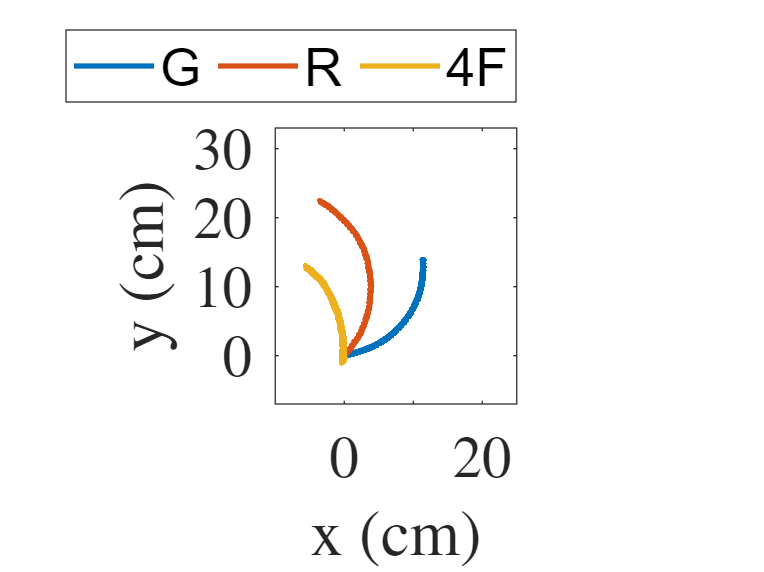

color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE", "#808080"];

figure
trial_nums = [3,17,26];
trial_labels = title_components(trial_nums,10);
plot_trajs(all_gaits, trial_nums, trial_labels, 2,[],color_array([1,2,3]))
%title('MTA4 Synthesized Translation Gaits')
ylim([-7 33])
xlim([-10 25])

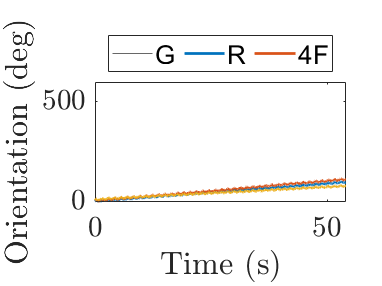



figure
plot_rot(all_gaits, trial_nums, trial_labels, 2,[],color_array([1,2,3]))
ylim([0 600])

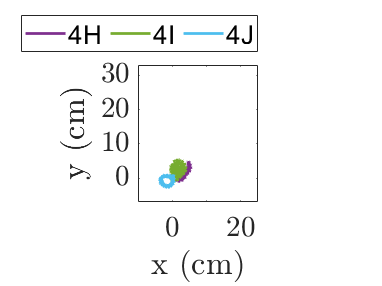


figure
trial_nums = [38,29,40];
trial_labels = title_components(trial_nums,10);
plot_trajs(all_gaits, trial_nums, trial_labels, 2,[],color_array(4:6))
%title('MTA4 Syntheiszed Rotation Gaits')
ylim([-7 33])
xlim([-10 25])

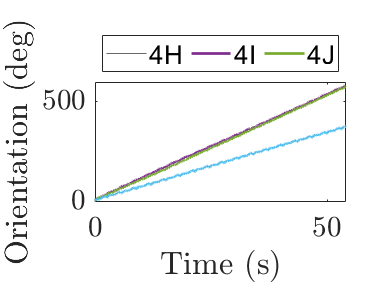



figure
plot_rot(all_gaits, trial_nums, trial_labels, 2,[],color_array(4:6))
ylim([0 600])

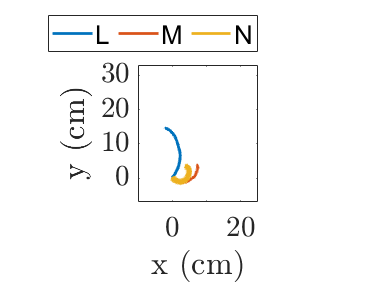


figure
trial_nums = [11,13,15];
trial_labels = title_components(trial_nums,10);
plot_trajs(all_gaits, trial_nums, trial_labels, 2,[],color_array(1:3))
%title('MTA4 Intuitive / Ad-Hoc Gaits')
ylim([-7 33])
xlim([-10 25])

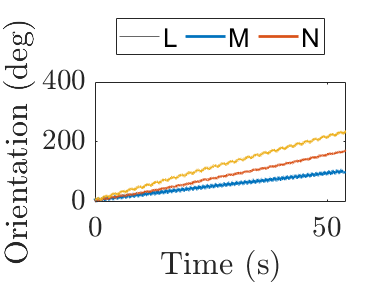



figure
plot_rot(all_gaits, trial_nums, trial_labels, 2,[],color_array(1:3))
ylim([0 400])

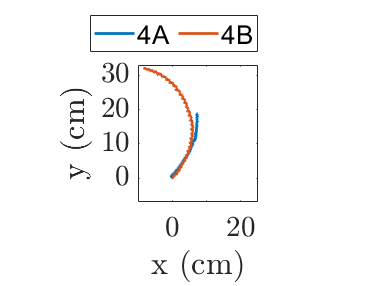


figure
trial_nums = [21,22];
trial_labels = title_components(trial_nums,10);
plot_trajs(all_gaits, trial_nums, trial_labels, 2,[],color_array(1:2))
%title('Loss-of-Limb MTA4 Syntheiszed Translation Gaits')
ylim([-7 33])
xlim([-10 25])

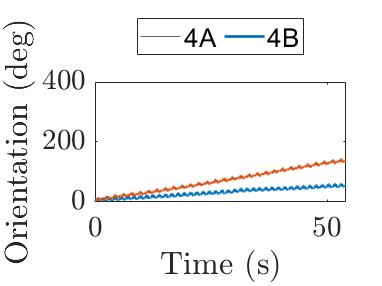


figure
plot_rot(all_gaits, trial_nums, trial_labels, 2,[],color_array(1:2))
ylim([0 400])

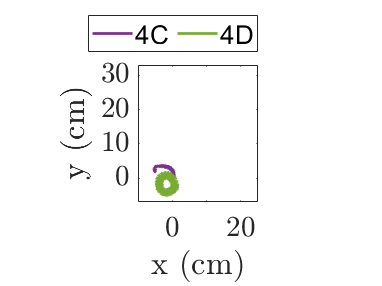


figure
trial_nums = [33,34];
trial_labels = title_components(trial_nums,10);
plot_trajs(all_gaits, trial_nums, trial_labels, 2,[],color_array(4:5))
%title('Loss-of-Limb MTA4 Syntheiszed Rotation Gaits')
ylim([-7 33])
xlim([-10 25])

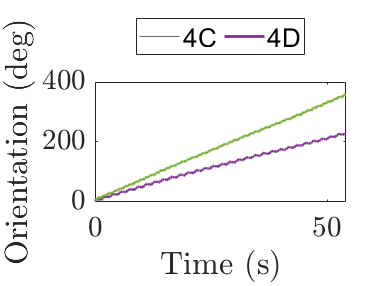



figure
plot_rot(all_gaits, trial_nums, trial_labels, 2,[],color_array(4:5))
ylim([0 400])

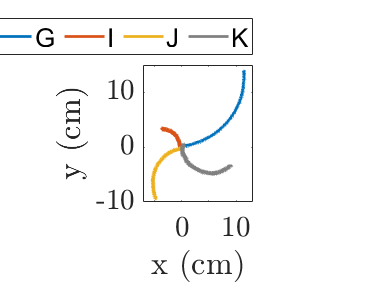


figure
trial_nums = [3,5,7,9];
trial_labels = title_components(trial_nums,10);
plot_trajs(all_gaits, trial_nums, trial_labels, 2,[],color_array([1,2,3,7]))
%title('Symmetric Permutation Comparison')
ylim([-10 15])
xlim([-7 13])

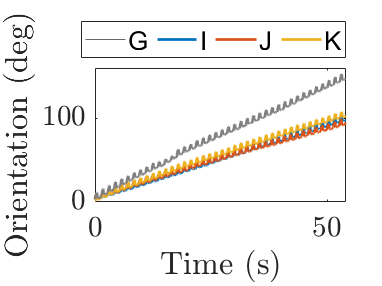



figure
plot_rot(all_gaits, trial_nums, trial_labels, 2,[],color_array([1,2,3,7]))
 ylim([0 160])

function plot_gait_char(trial_nums, trial_labels, speed_data, is_synth)
if is_synth
    l_color = "red";
else
    l_color = "blue";
    xlabel('Average Translational Speed (cm/s)')
    ylabel('Average Rotational Speed (deg/s)')
end
x = speed_data(1,trial_nums);
    x_err = speed_data(2,trial_nums);
    y = speed_data(3,trial_nums);
    y_err = speed_data(4,trial_nums);
    
    errorbar(x,y,y_err,y_err,x_err,x_err,"o","Color",l_color); 
for i = 1:length(trial_nums)
    text(x(i)+.01, y(i)-.2, "3"+trial_labels(i),"Color", l_color,'FontSize',16)
end
end


function plot_trajs(all_gaits, trial_nums, trial_labels, line_size, n_cycles, color_array)
if nargin<5
    n_cycles = [];
    color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE", "#808080"];
end
if nargin<6
    color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE", "#808080"];
end
k = 1;
hold on;
for i = trial_nums
    if isempty(n_cycles)
        idx_end = all_gaits(i).keyframes(60*2+2);
        p = plot(all_gaits(i).poses(1,1:idx_end), all_gaits(i).poses(2,1:idx_end));
        p.Color = color_array(k);
        p.LineWidth = line_size;
    else
        all_gaits(i).plot(n_cycles);
    end
    k = k+1;
end
xlabel('x (cm)')
ylabel('y (cm)')
daspect([1 1 1])
lgd = legend(trial_labels);
lgd.Location = "northoutside";
lgd.Orientation = "horizontal";
box on
end

function plot_rot(all_gaits, trial_nums, trial_labels, line_size, n_cycles, color_array)
if nargin<5
    n_cycles = [];
    color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE", "#808080"];
end
if nargin<6
    color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE", "#808080"];
end
k = 1;
hold on;
yline(0);
for i = trial_nums
    if isempty(n_cycles)
        idx_start = all_gaits(i).keyframes(2);
        idx_end = all_gaits(i).keyframes(60*2+2);
        timestamps = all_gaits(i).timestamps(idx_start:idx_end)-...
                     all_gaits(i).timestamps(idx_start);
        global_theta = rad2deg(unwrap(all_gaits(i).poses(3,idx_start:idx_end)));
        p = plot(timestamps, global_theta);
        p.Color = color_array(k);
        p.LineWidth = line_size;
    else
        all_gaits(i).plot(n_cycles);
    end
    k = k+1;
end
ylabel('Orientation (deg)')
xlabel('Time (s)')
xlim([0 54])
lgd = legend(trial_labels);
lgd.Location = "northoutside";
lgd.Orientation = "horizontal";
box on
end



function twists_plot = plot_twists(twists, global_theta, trial_nums, trial_labels, ylims)
    figure;
    twists_plot = tiledlayout(3,2);
    ylabels = {'$v_x$ (cm/s)', '$v_y$ (cm/s)', '$\omega$ (deg/s)'};

    % Plot twist components vs number of gait cycles.
    for i = 1:3
        nexttile(2*i - 1);
        hold on;
        for j = 1:length(trial_nums)        
            plot(twists{trial_nums(j)}(i,:))
        end
        ylabel(ylabels{i}, 'FontSize',14)
        if ~isempty(ylims)
            ylim(ylims(i,:))
        end
    end
    xlabel('Number of Gait Cycles', 'FontSize',14)
    
    % Plot twist components vs global robot orientation.
    for i = 1:3
        nexttile(2*i);
        hold on;
        for j = 1:length(trial_nums)        
            scatter(rad2deg(global_theta{trial_nums(j)}(1,:)),twists{trial_nums(j)}(i,:))
        end
        xlim([-180 180])
        ylabel(ylabels{i}, 'FontSize',14)
        if ~isempty(ylims)
            ylim(ylims(3+i,:))
        end
    end
    xlabel('Global robot orientation $\theta_G$ (deg)', 'FontSize',14)

    if length(trial_labels) > 1
        lgd = legend(trial_labels, 'FontSize',18);
        lgd.Orientation = 'horizontal';
        lgd.Layout.Tile = 'north';
    else
        plot_title = ['Twist (body velocity) for', trial_labels];
        title(twists_plot,plot_title, 'FontSize',22) 
    end
end

function plot_ICR(cent_rot, rad_curv, trial_nums, trial_labels, ylims)
figure
tiledlayout(2,1)
for i = trial_nums
    nexttile(1)
    hold on;
    scatter(cent_rot{i}(1,:), cent_rot{i}(2,:),'*')
    nexttile(2)
    hold on;
    plot(1:length(rad_curv{i}(1,:)), rad_curv{i}(1,:))
end
nexttile(1)
title('Instantaneous center of rotation IC')
xlabel('x (cm)')
if ~isempty(ylims)
    ylim(ylims(1,:))
end
ylabel('y (cm)')
daspect([1 1 1]);
nexttile(2)
if ~isempty(ylims)
    ylim(ylims(2,:))
end
lgd = legend(trial_labels, 'Orientation', 'Horizontal');
lgd.Layout.Tile = 'north';

title('Radius of curvature')
xlabel('Number of Gait Cycles')
ylabel('$\| IC\|  (cm)$')
end